# Phase Difference Analysis

#### Select subjects

clearvars;
filepath        = '/Users/researcher/Desktop/SWM Study/Experiments/Experiment2_2AFC/PhaseAnalysis';
subjects        = CleanDir(filepath);

fakeUI          = figure;
fakeUI.UserData = subjects;
fakeUI.Visible  =  'off';
select_labels(fakeUI,[],subjects);
waitfor(findall(0,'Name','Select Labels'),'BeingDeleted','on');
subjects        = fakeUI.UserData;
close(fakeUI);

layout          = 'C:\Users\User\Documents\GitHub\Deci\Function\Gen_Fun\easycap_rob_eye.mat';


#### Subject-wise WW-test

version = [];
showlaplace     = true;
showhilbert     = false;
if showlaplace == true
    version = [version '_laplace'];
end
if showhilbert == true
    version = [version '_hilbert'];
end

for subs = 1:length(subjects)
    director = [filepath filesep subjects{subs} filesep subjects{subs} version]; 
    stimlocked  = load([director '_lock1_phase.mat'],'dhist','dav','cellperms');  % dhists are chan*chan*timeperiod_of_interest*trial matrices
    d3locked    = load([director '_lock2_phase.mat'],'dhist','dav','cellperms');
    
    % sort channel labels according to position on the head
    stimlocked  = sortcells(stimlocked);
    d3locked    = sortcells(d3locked);
    
    % Comparing D1 (dhist1(:,:,1,:)) and D3 (dhist2(:,:,1,:))
    for chani = 1:size(stimlocked.dhist,1)
        for chanj = 1:size(stimlocked.dhist,2)
            [wwtest(subs).pval(chani,chanj), wwtest(subs).fstat(chani,chanj), wwtest(subs).table{chani,chanj},wwtest(subs).rw(chani,chanj)] = circ_wwtest((stimlocked.dhist(chani,chanj,1,:)),(d3locked.dhist(chani,chanj,1,:)));
        end
    end 
    
    % Generate plots which show significance
    plottest(subs) = wwtest(subs);
    % Retain only one diagonal matrix
    if size(plottest(subs).pval,1) == size(plottest(subs).pval,2)
        for i = 1:size(plottest(subs).pval,1)
            plottest(subs).pval(i,i:end)    = NaN;
            plottest(subs).fstat(i,i:end)   = NaN;
            plottest(subs).rw(i,i:end)      = NaN;
        end
    end
    
    % Remove elements with unacceptablye high p-values or very low
    plottest(subs).pval((plottest(subs).pval >= (0.05/(58*58))) | (plottest(subs).rw < 0.45)) = NaN; 
    figure('units','normalized','outerposition',[0 0 1 1]);
    imagesc(plottest(subs).pval);
%     imagesc(plottest(subs).pval<(0.05/(58*58)) & plottest(subs).rw>0.45)
    xticks(1:length(stimlocked.cellperms{1}));
    yticks(1:length(stimlocked.cellperms{2}));
    xticklabels(stimlocked.cellperms{1});
    yticklabels(stimlocked.cellperms{1});
    xlabel('Channels');
    ylabel('Channels');
    axis square
    xtickangle(45)
    ytickangle(45)
end


#### Validation - Plot histograms of significant pairs

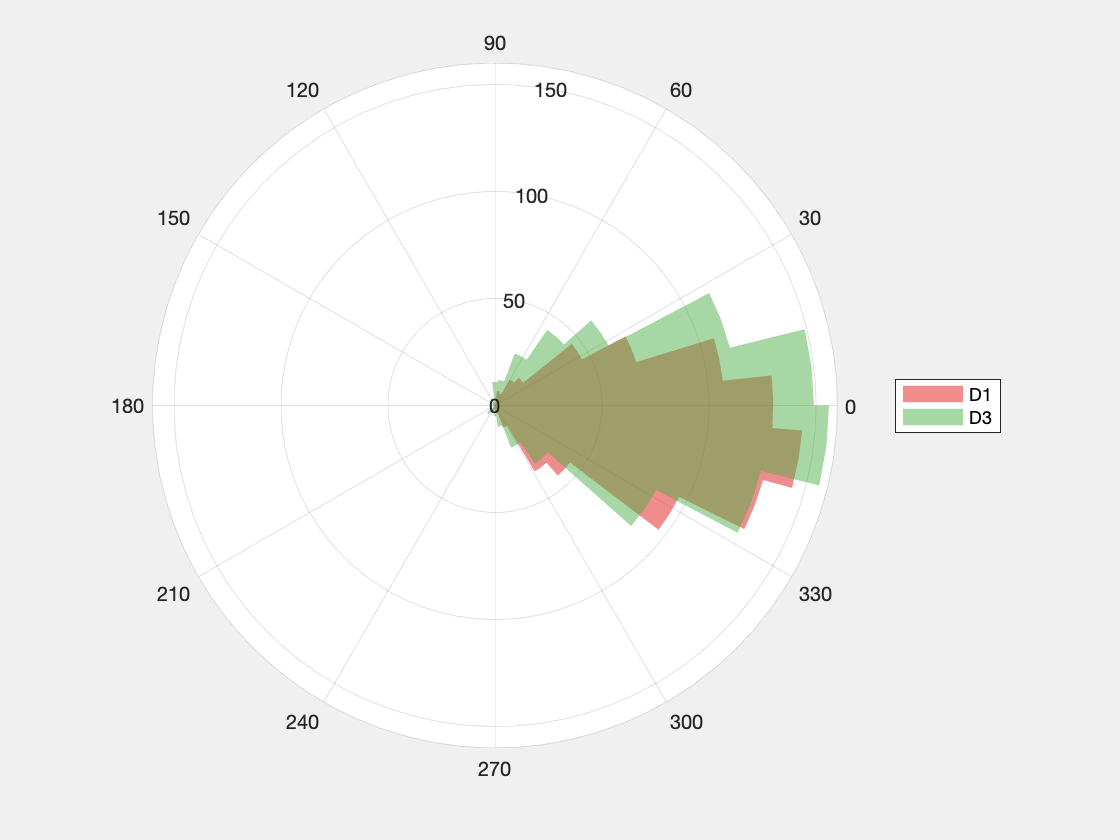

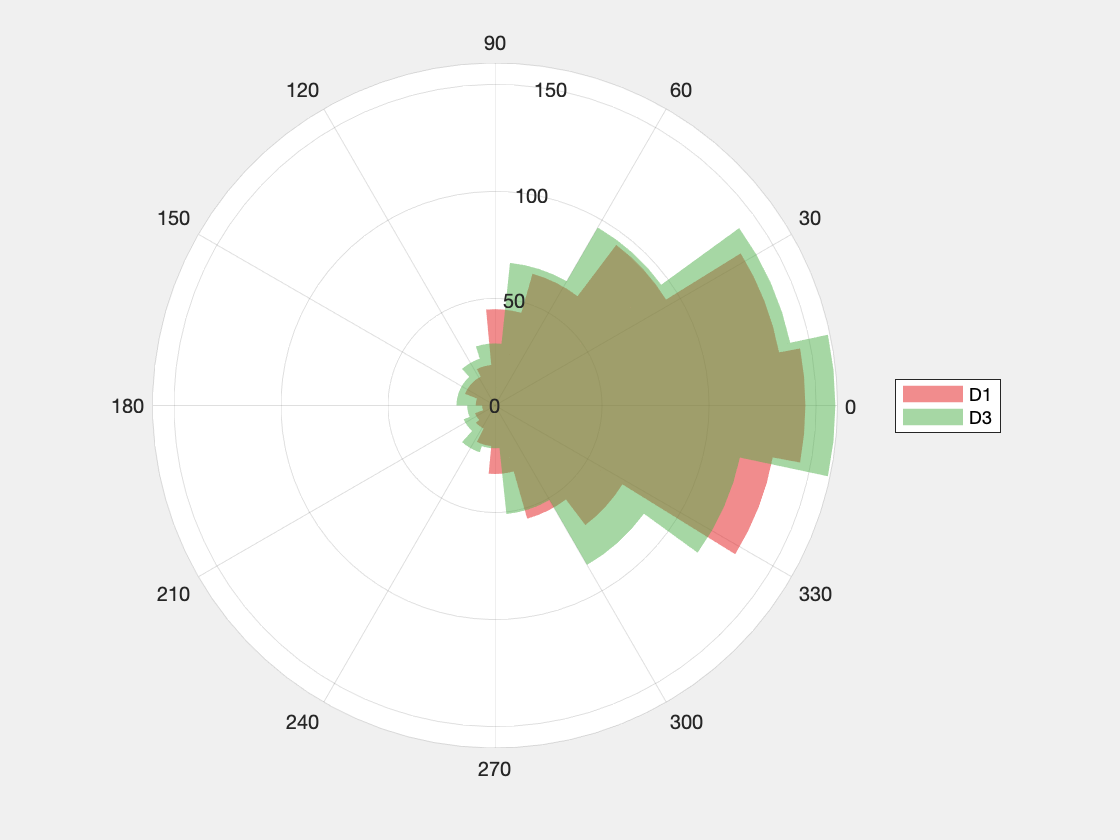

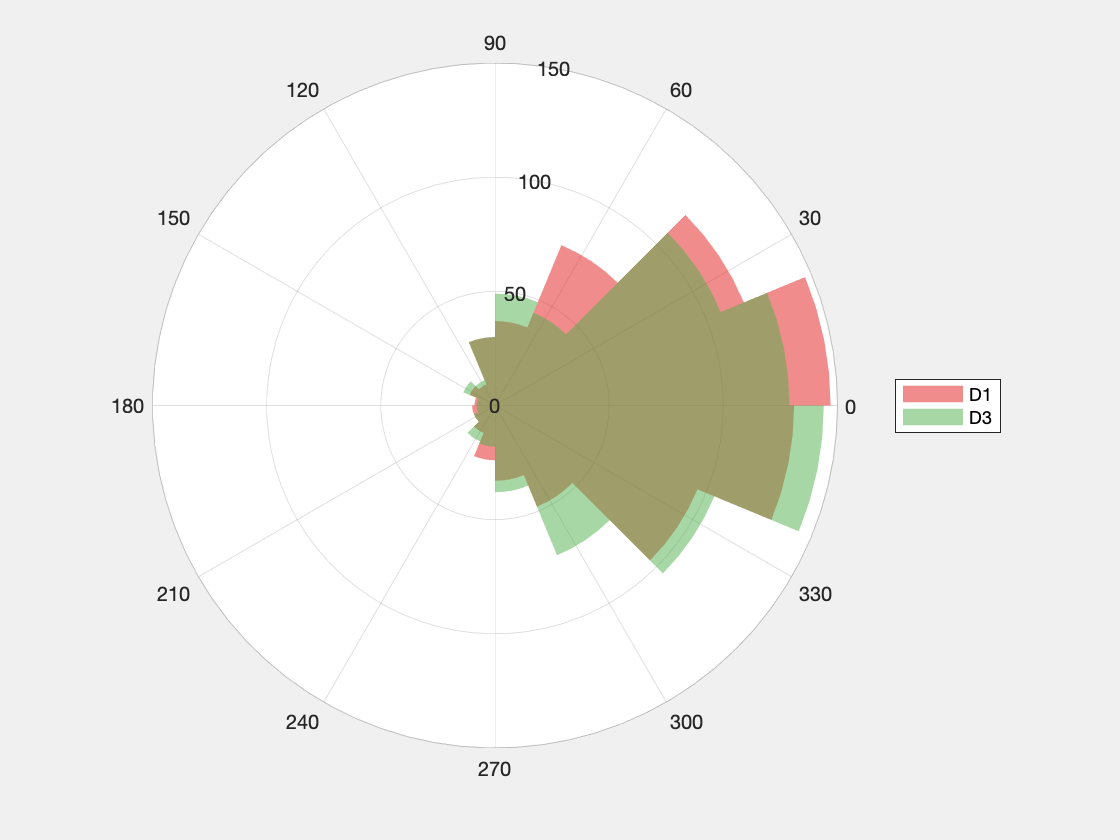

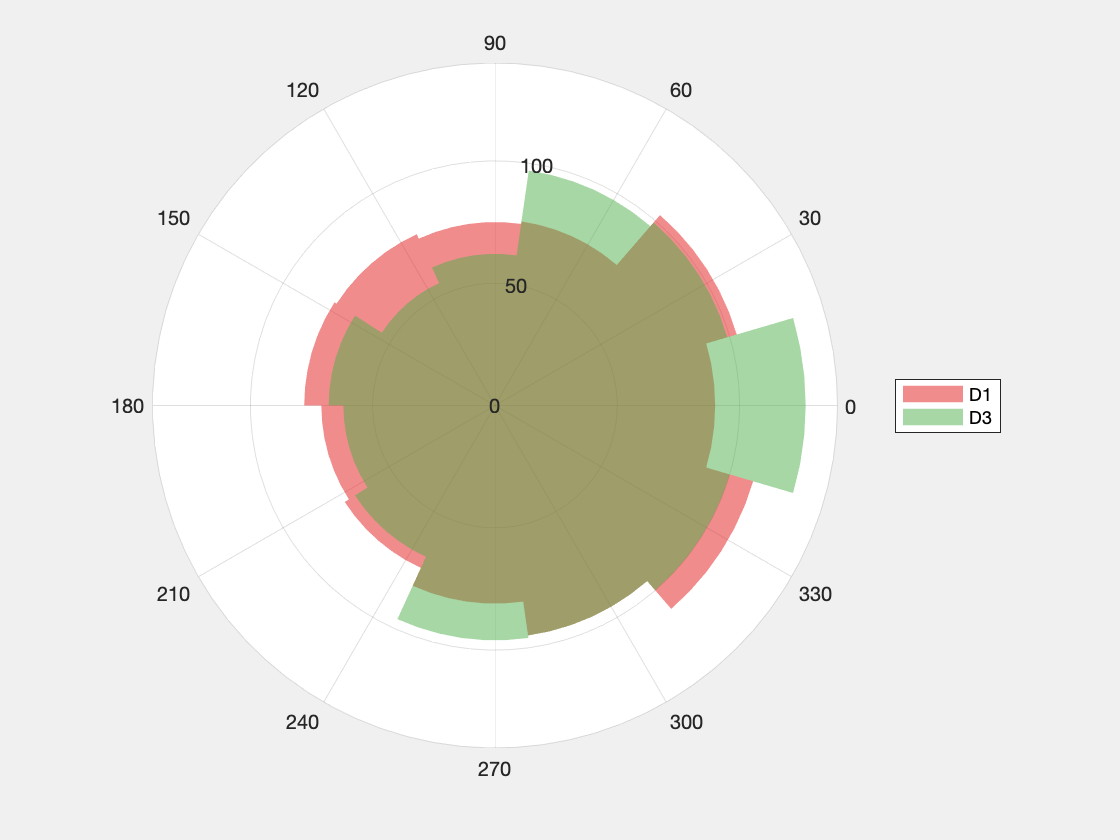

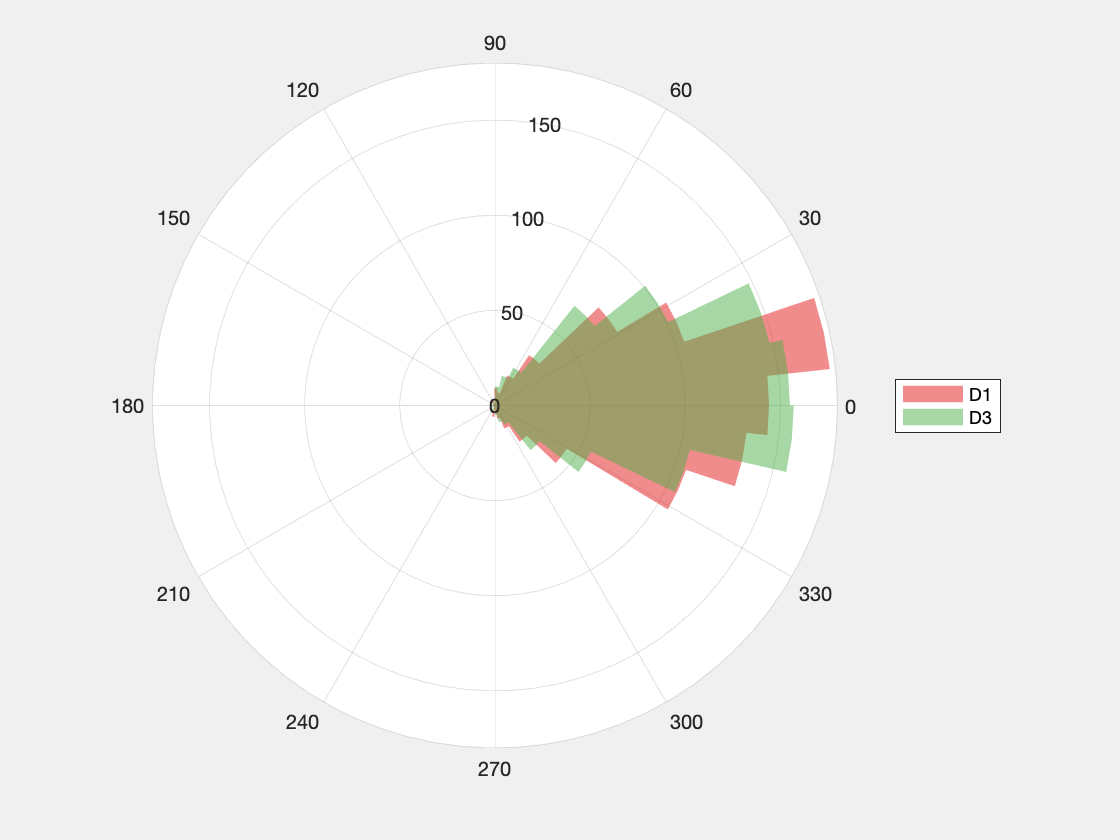

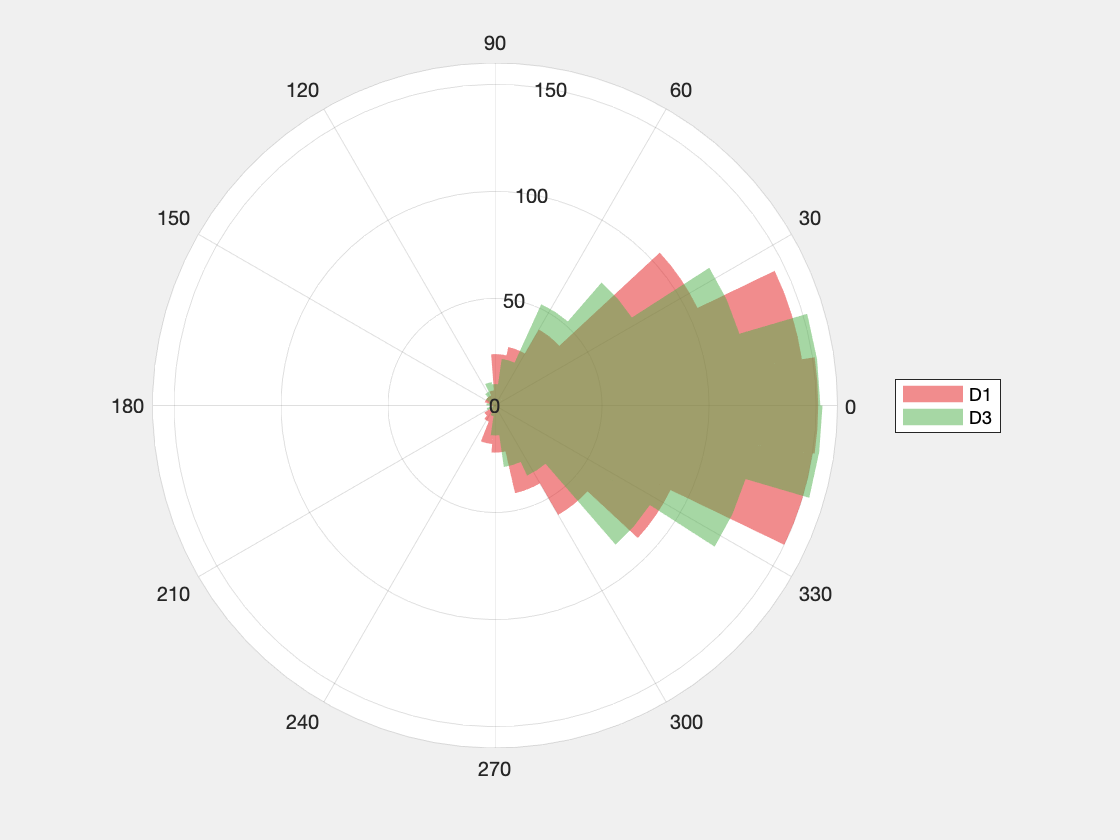

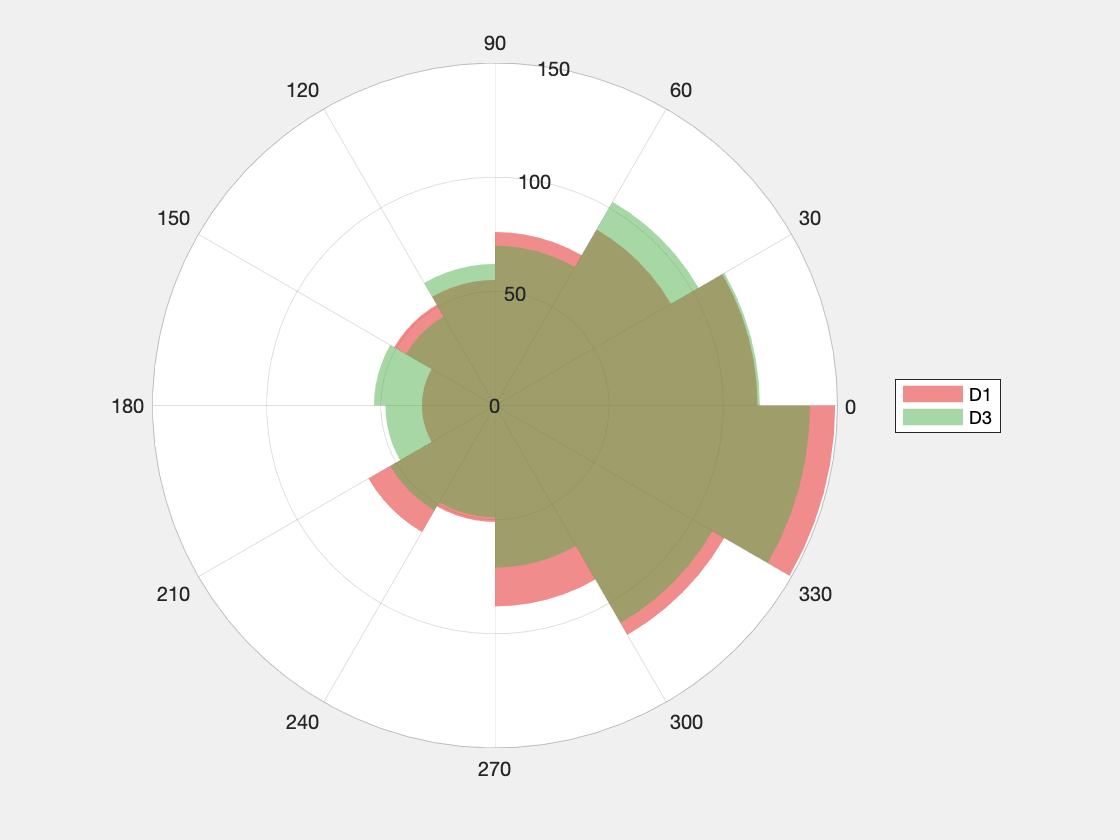

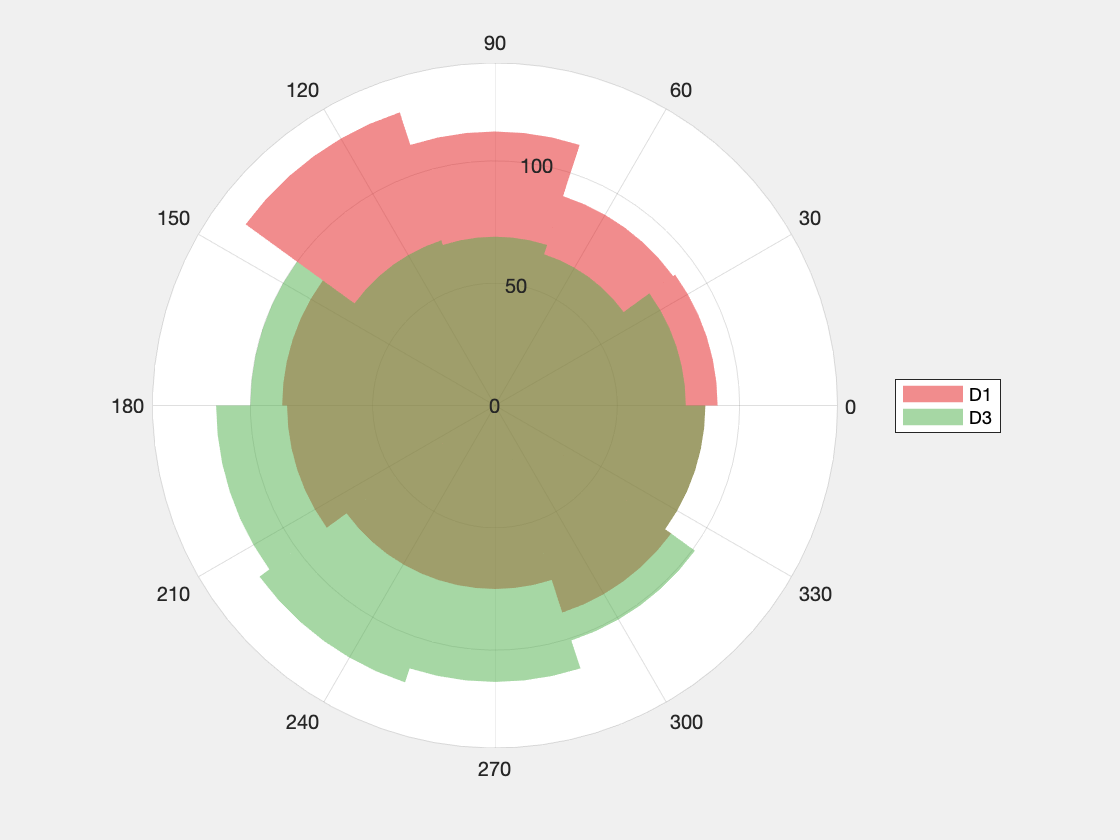

version = [];
showlaplace     = true;
showhilbert     = false;
if showlaplace == true
    version = [version '_laplace'];
end
if showhilbert == true
    version = [version '_hilbert'];
end

chanpair = {'PO3','PO4'};

% Colormap
map = brewermap(4,'Set1');

for subs = 1:length(subjects)
    director = [filepath filesep subjects{subs} filesep subjects{subs} version];
    
    if ~exist('stimlocked','var')
        stimlocked  = load([director '_lock1_phase.mat'],'dhist','dav','cellperms');  % dhists are chan*chan*timeperiod_of_interest*trial matrices
    end
    if ~exist('d3locked','var')
        d3locked    = load([director '_lock2_phase.mat'],'dhist','dav','cellperms');
    end
    
    d1hist = stimlocked.dhist(ismember(stimlocked.cellperms{1},chanpair{1}),ismember(stimlocked.cellperms{2},chanpair{2}),1,:);
    d3hist = d3locked.dhist(ismember(d3locked.cellperms{1},chanpair{1}),ismember(d3locked.cellperms{2},chanpair{2}),1,:);
    
    polars(subs) = figure;
    f1 = polarhistogram(d1hist,'facecolor',map(1,:),'facealpha',.5,'edgecolor','none');
    hold on;
    f3 = polarhistogram(d3hist,'facecolor',map(3,:),'facealpha',.5,'edgecolor','none');
    hold on;
    legend([f1 f3],{'D1','D3'});
    polars(subs).Visible = 'on';
    clear stimlocked d3locked d1hist d3hist
end

#### Simulations on circ_wwtest

d1 = deg2rad(randi([-160 160],1000,1));
d2 = deg2rad(randi([-70 55],1000,1));

map = brewermap(4,'Set1');
polarhistogram(d1,'facecolor',map(1,:),'facealpha',.5,'edgecolor','none');
hold on;
polarhistogram(d2,'facecolor',map(3,:),'facealpha',.5,'edgecolor','none');

[p,f,tab,rw] = circ_wwtest(d1, d2)


#### Rotating data for cross-subject normalization

version = [];
showlaplace     = false;
showhilbert     = false;
if showlaplace == true
    version = [version '_laplace'];
end
if showhilbert == true
    version = [version '_hilbert'];
end

% Run a loop across subjects
for subs = 1:length(subjects)
    director = [filepath filesep subjects{subs} filesep subjects{subs} version]; 
    stimlocked  = load([director '_lock1_phase.mat'],'dhist','dav','cellperms');  % dhists are chan*chan*timeperiod_of_interest*trial matrices
    d3locked    = load([director '_lock2_phase.mat'],'dhist','dav','cellperms');
    
    % sort channel labels according to position on the head
    stimlocked  = sortcells(stimlocked);
    d3locked    = sortcells(d3locked); 

    subcoef = nan(size(stimlocked.dhist,1),size(stimlocked.dhist,2));
    % For each subject, project the D1 distribution into the complex space,
    % average complex D1s and determine the mean angle
    for xi = 1:size(stimlocked.dhist,1)
        for yi = 1:size(stimlocked.dhist,2)
            % subtraction angle
            subcoef(xi,yi) = -1*angle(mean(exp(1i.*(stimlocked.dhist(xi,yi,1,:)))));
            
            % subtract this angle from D1, D2, D3 and D4 distributions
            rotated(subs).stimlock.d1(xi,yi,:) = angle(exp(1i.*stimlocked.dhist(xi,yi,1,:)).*(exp(1i*subcoef(xi,yi))));
            rotated(subs).stimlock.d2(xi,yi,:) = angle(exp(1i.*stimlocked.dhist(xi,yi,2,:)).*(exp(1i*subcoef(xi,yi))));
            rotated(subs).d3lock.d3(xi,yi,:)   = angle(exp(1i.*d3locked.dhist(xi,yi,1,:)).*(exp(1i*subcoef(xi,yi))));
            rotated(subs).d3lock.d4(xi,yi,:)   = angle(exp(1i.*d3locked.dhist(xi,yi,2,:)).*(exp(1i*subcoef(xi,yi))));
            
%             rotated(subs).stimlock.d1(xi,yi,:) = stimlocked.dhist(xi,yi,1,:) - subcoef(xi,yi);
%             rotated(subs).stimlock.d2(xi,yi,:) = stimlocked.dhist(xi,yi,2,:) - subcoef(xi,yi);
%             rotated(subs).d3lock.d3(xi,yi,:)   = d3locked.dhist(xi,yi,1,:) - subcoef(xi,yi);
%             rotated(subs).d3lock.d4(xi,yi,:)   = d3locked.dhist(xi,yi,2,:) - subcoef(xi,yi);
%             
            % store original data in a similar format for ease
            % subtract this angle from D1, D2, D3 and D4 distributions
            original(subs).stimlock.d1(xi,yi,:) = stimlocked.dhist(xi,yi,1,:);
            original(subs).stimlock.d2(xi,yi,:) = stimlocked.dhist(xi,yi,2,:);
            original(subs).d3lock.d3(xi,yi,:)   = d3locked.dhist(xi,yi,1,:);
            original(subs).d3lock.d4(xi,yi,:)   = d3locked.dhist(xi,yi,2,:);

        end
    end
    rotated(subs).cellperms = stimlocked.cellperms;
    original(subs).cellperms = stimlocked.cellperms;
    
    clear stimlocked d3locked
end


#### Visual inspection after rotation

% Plot D1 and D3 distributions for an example pair of electrodes before and
% after rotation for visual inspection
map = brewermap(4,'Set1');

chan1 = 8; chan2 = 56; %randomly chosen

for subs = 1:length(subjects)
    figure(subs);
    
    subplot(1,2,1);
    f1 = polarhistogram(original(subs).stimlock.d1(chan1,chan2,:),10,'facecolor',map(1,:),'facealpha',.5,'edgecolor','none');
    hold on;
    f3 = polarhistogram(original(subs).d3lock.d3(chan1,chan2,:),10,'facecolor',map(3,:),'facealpha',.5,'edgecolor','none');
    hold on;
    legend([f1 f3],{'D1','D3'});
    polars(subs).Visible = 'on';
    title([subjects{subs} 'Original'])
    rlim([0 200])
    
    subplot(1,2,2);
    f1 = polarhistogram(rotated(subs).stimlock.d1(chan1,chan2,:),10,'facecolor',map(1,:),'facealpha',.5,'edgecolor','none');
    hold on;
    f3 = polarhistogram(rotated(subs).d3lock.d3(chan1,chan2,:),10,'facecolor',map(3,:),'facealpha',.5,'edgecolor','none');
    hold on;
    legend([f1 f3],{'D1','D3'});
    polars(subs).Visible = 'on';
    title([subjects{subs} 'Rotated'])
    rlim([0 200])
end


#### Paired t-test  across subjects on mean phase difference angles

if ~exist('rotated','var')
    error('Run section on rotating data first.');
end
for subs = 1:length(subjects)
   for xi = 1:size(rotated(subs).stimlock.d1,1)
       for yi = 1:size(rotated(subs).stimlock.d1,2)
           d1av(subs,xi,yi) = angle(mean(exp(1i.*(rotated(subs).stimlock.d1(xi,yi,:))))); % this will be an internal check to confirm rotation happened properly. These values should be zero.
           d3av(subs,xi,yi) = angle(mean(exp(1i.*(rotated(subs).d3lock.d3(xi,yi,:)))));
       end
   end
   
end

for xi = 1:size(d1av,2)
   for yi = 1:size(d1av,3)
       [h(xi,yi),p(xi,yi),~,stats{xi,yi}] = ttest(d1av(:,xi,yi),d3av(:,xi,yi));
   end
end

for i = 1:size(p,1)
    p(i,i:end)    = NaN;
end
 
figure('units','normalized','outerposition',[0 0 1 1]);
imagesc(p<(0.05/(58*58)))
% imagesc(p<(1e-04))
xticks(1:length(rotated(1).cellperms{1}));
yticks(1:length(rotated(1).cellperms{2}));
xticklabels(rotated(1).cellperms{1});
yticklabels(rotated(1).cellperms{2});
xlabel('Channels');
ylabel('Channels');
axis square
xtickangle(45)
ytickangle(45)


#### Determining circular variance of the two delay periods

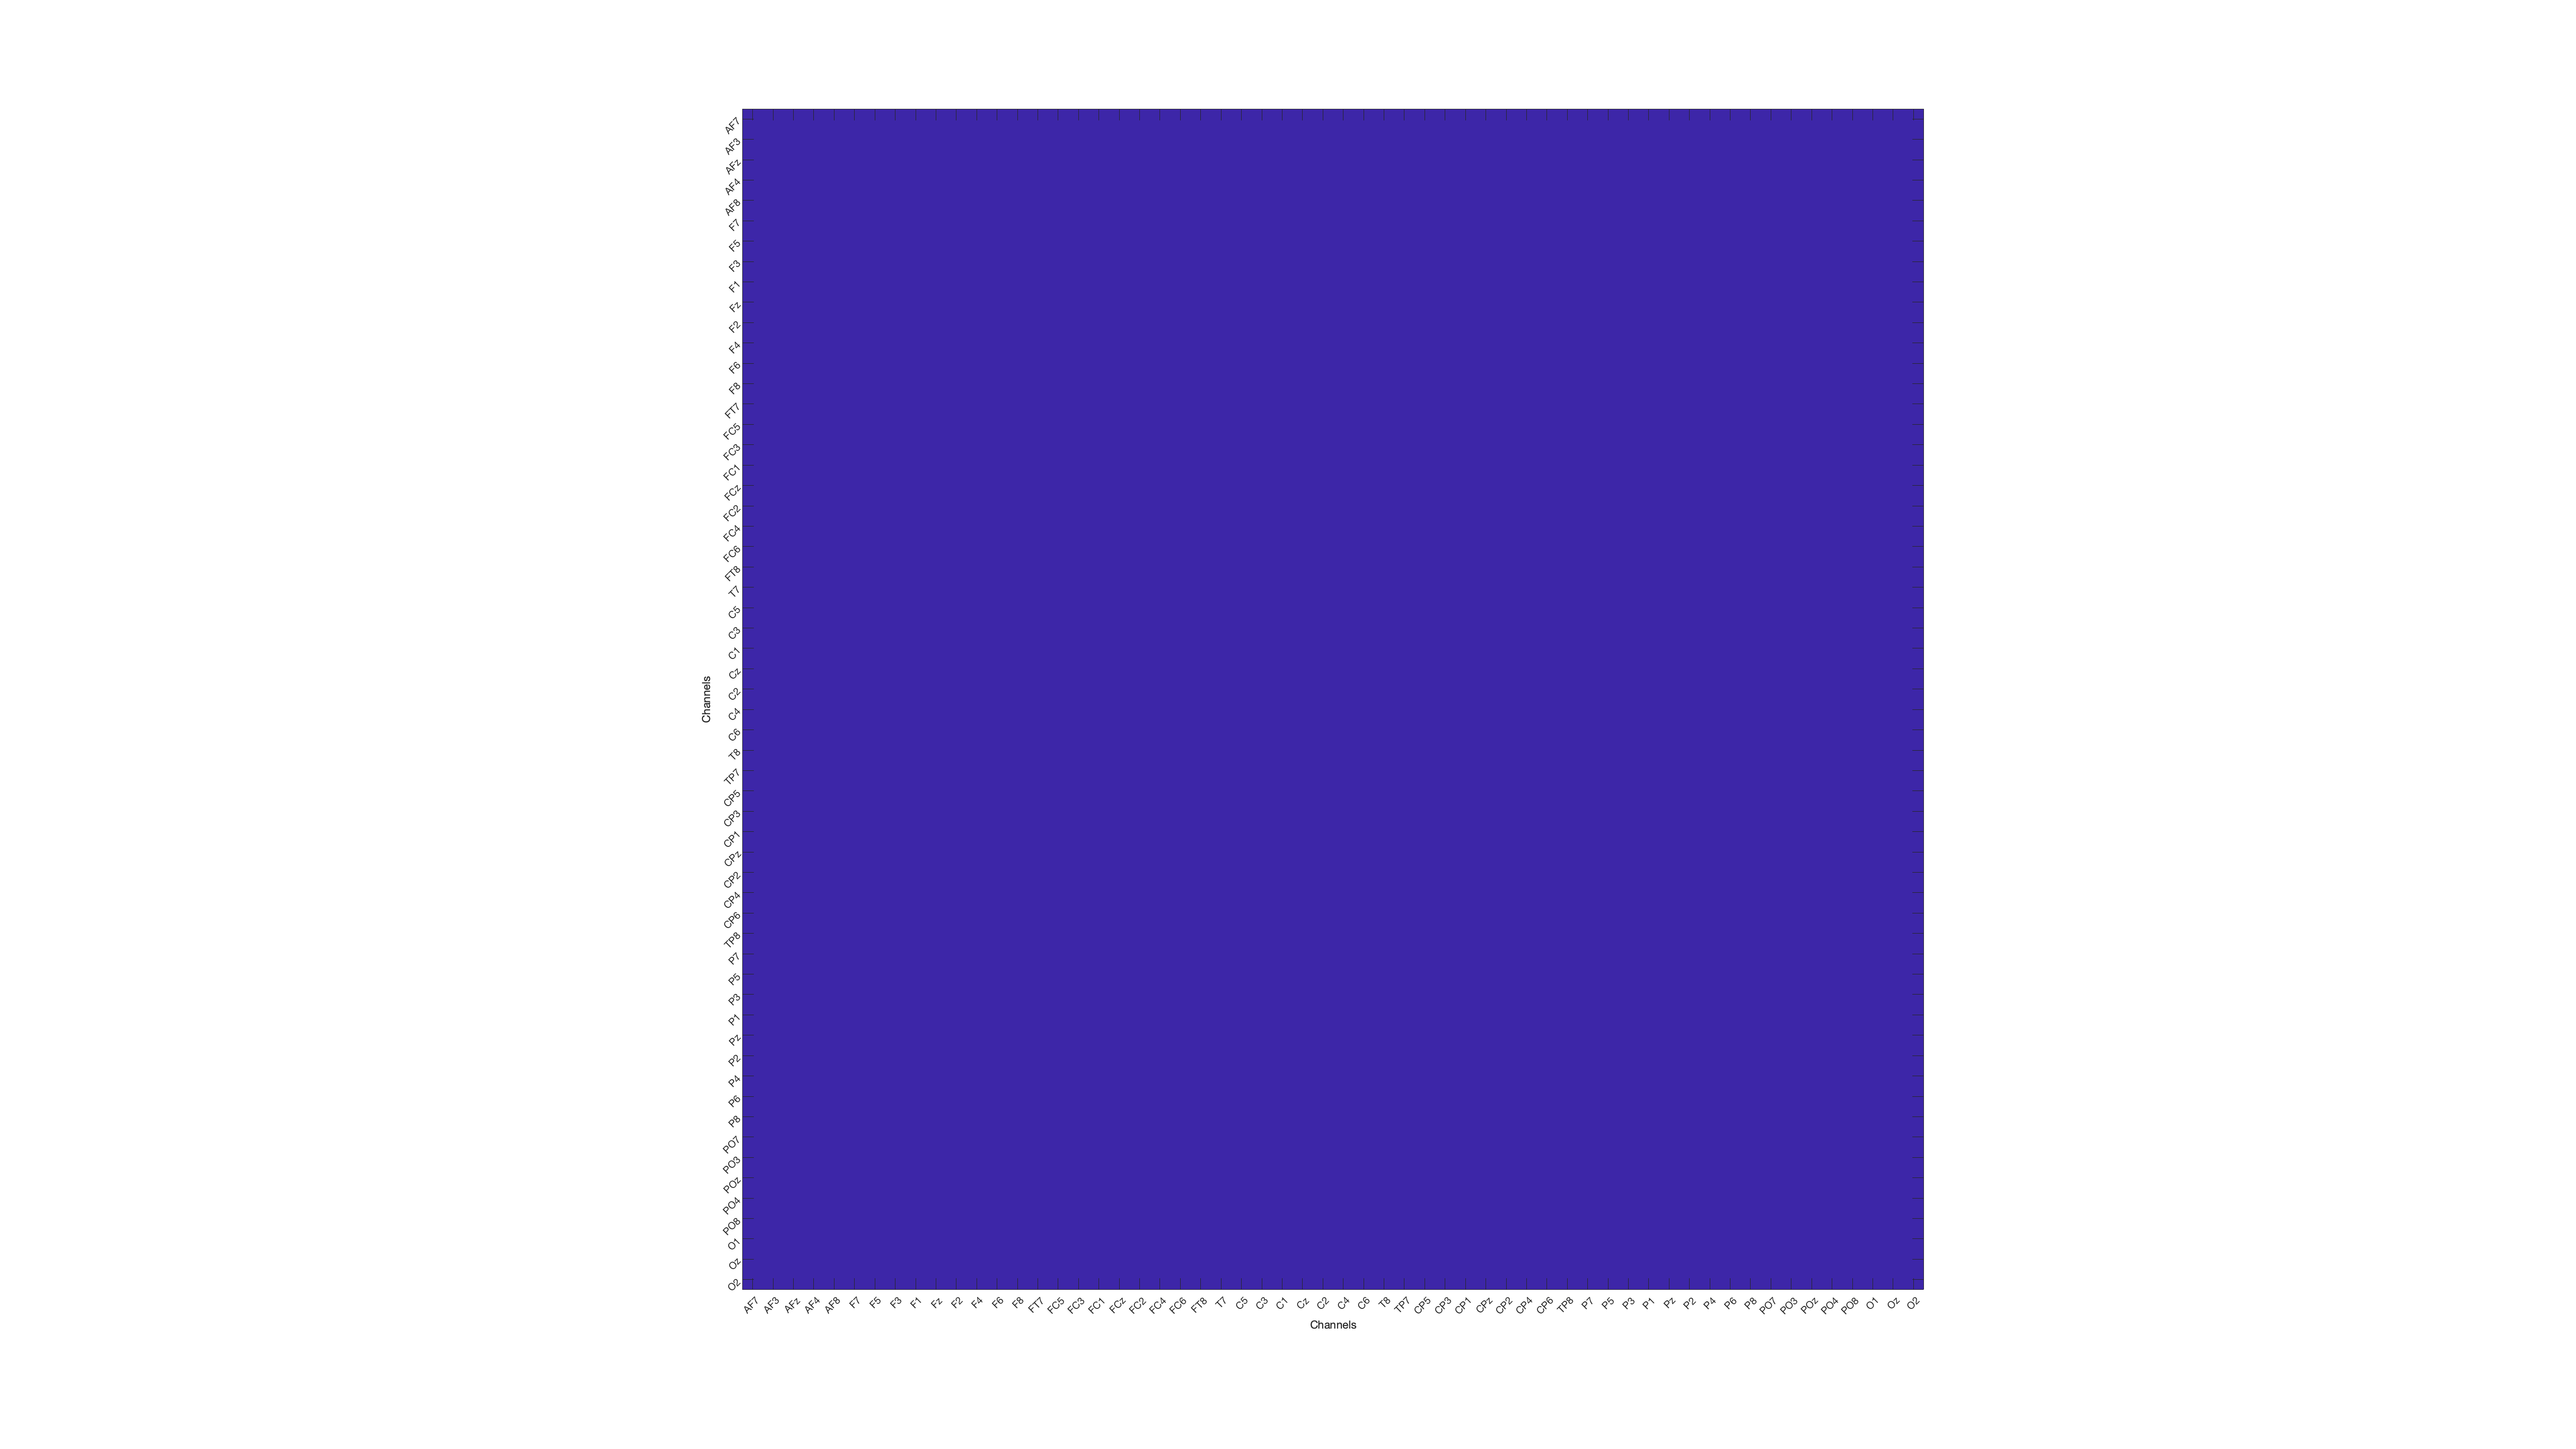

version = [];
showlaplace     = false;
showhilbert     = false;
if showlaplace == true
    version = [version '_laplace'];
end
if showhilbert == true
    version = [version '_hilbert'];
end

% Run a loop across subjects
for subs = 1:length(subjects)
    director = [filepath filesep subjects{subs} filesep subjects{subs} version]; 
    stimlocked  = load([director '_lock1_phase.mat'],'dhist','dav','cellperms');  % dhists are chan*chan*timeperiod_of_interest*trial matrices
    d3locked    = load([director '_lock2_phase.mat'],'dhist','dav','cellperms');
    
    % sort channel labels according to position on the head
    stimlocked  = sortcells(stimlocked);
    d3locked    = sortcells(d3locked); 
    
    for xi = 1:size(stimlocked.dhist,1)
        for yi = 1:size(stimlocked.dhist,2)
            d1var(subs,xi,yi) = circ_var(stimlocked.dhist(xi,yi,1,:));
            d3var(subs,xi,yi) = circ_var(d3locked.dhist(xi,yi,1,:));
        end
    end
end

for xi = 1:size(d1var,2)
   for yi = 1:size(d1var,3)
       [h(xi,yi),p(xi,yi),~,stats{xi,yi}] = ttest(d1var(:,xi,yi),d3var(:,xi,yi));
   end
end
        
figure('units','normalized','outerposition',[0 0 1 1]);
imagesc(p<(0.05/(58*58)))
% imagesc(p<(1e-04))
xticks(1:length(stimlocked.cellperms{1}));
yticks(1:length(stimlocked.cellperms{2}));
xticklabels(stimlocked.cellperms{1});
yticklabels(stimlocked.cellperms{2});
xlabel('Channels');
ylabel('Channels');
axis square
xtickangle(45)
ytickangle(45)